## Load CMI_data and reshape to 15 min records

load CMI_data

t = reshape(CMI.t,900,1200);
p2 = reshape(CMI.p2,900,1200);
p3 = reshape(CMI.p3,900,1200);
p4 = reshape(CMI.p4,900,1200);
p6 = reshape(CMI.p6,900,1200);
p7 = reshape(CMI.p7,900,1200);
e7 = reshape(CMI.e7,900,1200);

## Compute Spectragram

Sp2 = NaN(450,1200);
Se7 = NaN(450,1200);

for j = 1:1200
    [Sp2(:,j),f] = autospec(p2(:,j),1,5,.05);
    [Se7(:,j),f] = autospec(e7(:,j),1,5,.05);
end

tm = mean(t);

## Plot Spectragram

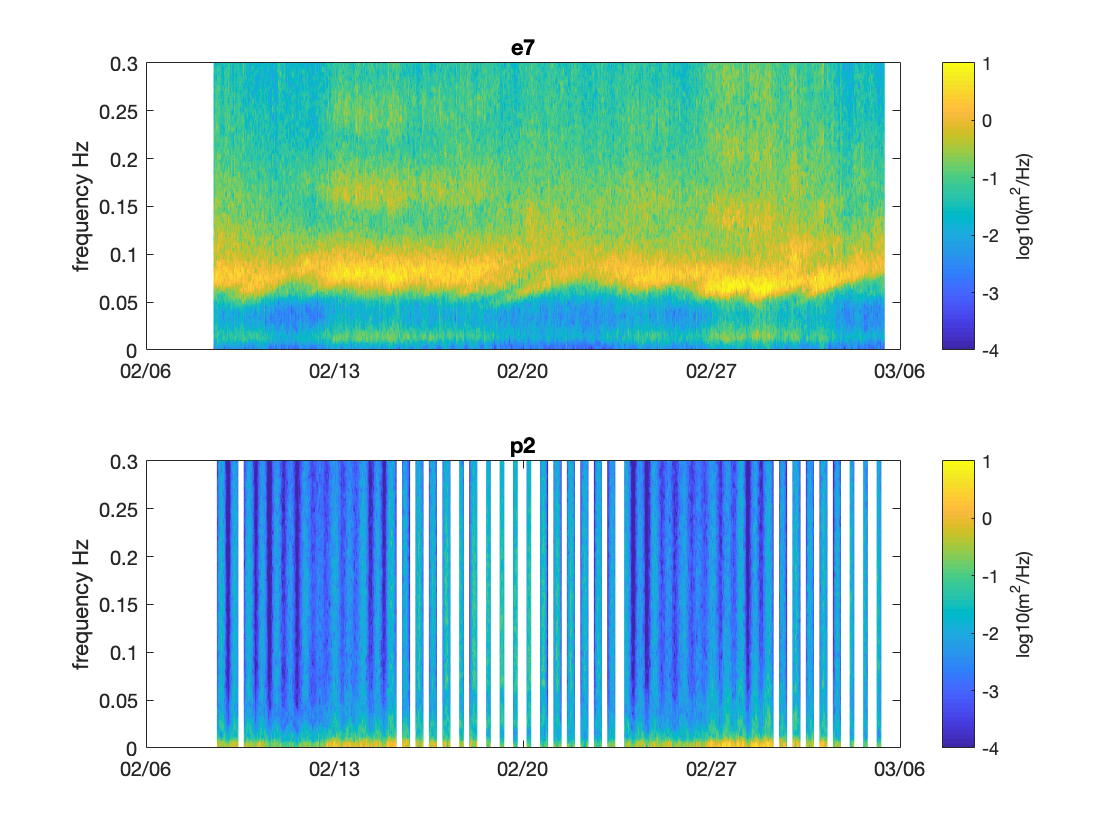

figure (1)
clf
subplot(211)
pcolor(tm,f,log10(Se7))
shading interp
datetick
ylabel('frequency Hz')
c = colorbar;
caxis([-4 1]);
ylabel(c,'log10(m^2/Hz)')
ylim([0 .3])
title('e7')
subplot(212)
pcolor(tm,f,log10(Sp2))
shading interp
datetick
ylabel('frequency Hz')
c = colorbar;
caxis([-4 1]);
ylabel(c,'log10(m^2/Hz)')
ylim([0 .3])
title('p2')

white areas, low tide, no water on reef at p2 - no energy

very small yellow signal on bottom of p2 plot, which is infragravity energy, not seen in e7 plot

## Plot vs period

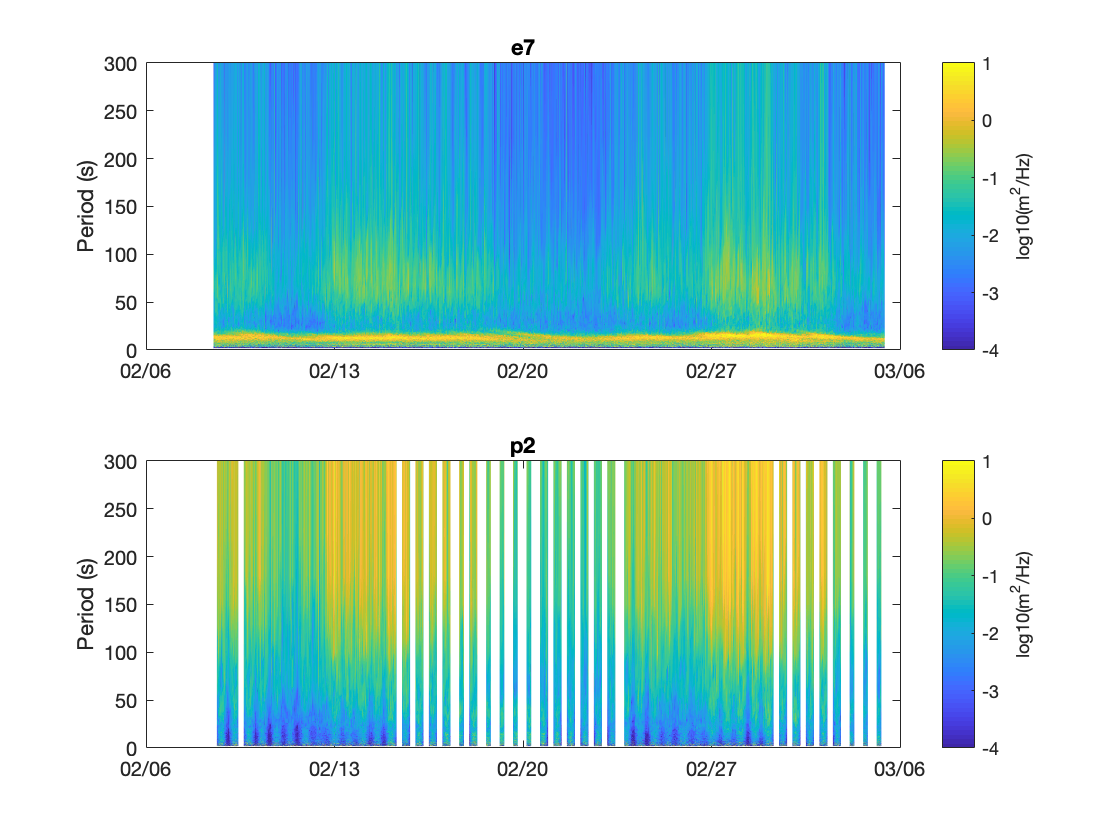

figure (2)
clf
subplot(211)
pcolor(tm,1./f,log10(Se7))
shading interp
datetick
ylabel('Period (s)')
c = colorbar;
caxis([-4 1]);
ylabel(c,'log10(m^2/Hz)')
ylim([0 300])
title('e7')
subplot(212)
pcolor(tm,1./f,log10(Sp2))
shading interp
datetick
ylabel('Period (s)')
c = colorbar;
caxis([-4 1]);
ylabel(c,'log10(m^2/Hz)')
ylim([0 300])
title('p2')

Plotting is opposite of other plot above, really seeing the 